# MC method

# 1. 参数

clear;clc;

% 随机种子
rng(1)

% 采样
n = 2000;
N = 1.05*n;
P = 11;
param = {'A' 'T' 'α' 'n' 'Porosity' 'K' 'Dl' 'DOr' 'Henry' 'KDO' 'μmax'};
% A T α n Porosity K Dl DOr Henry KDO μmax
X0 = sobolr(N, P); 
x = X0;
x(:,6) = sobolln(x(:,6));
x(:,9:11) = soboln(x(:,9:11));

% 去界外值
i2 = 0;
for i1 = 1:N
    if x(i1,6)>13 || max(abs(x(i1,9:11)))>3 
        i2 = i2+1;
        id(i2) = i1;
    end
end
if i2>0
    x(id,:) = [];
end

% 生成参数
param_values = [0.1+0.4*x(:,1), 2+5*x(:,2), ...  % 'A' 'T'
                1.6+0.8*x(:,3), 1.2+0.6*x(:,4), ... % 'α' 'n'  
                0.20+0.15*x(:,5), 146.9+(1036.8-146.9)/13*x(:,6), ... % 'Porosity' 'K'
                0.1+4.9*x(:,7), 0.28+0.15*x(:,8), ... % 'Dl' 'DOr' 
                25.6+(32.6-25.6)/2+(32.6-25.6)/6*x(:,9), ... % 'Henry' 
                0.0009375+(0.009375-0.0009375)/2+(0.009375-0.0009375)/6*x(:,10), ... % 'KDO'
                0.09375+(0.478-0.09375)/2+(0.478-0.09375)/6*x(:,11)]; % 'μmax'
param_values = param_values(1:n,:);
clear i1 i2 id x X0 param P;

# 2. 模拟&计算

yloc = [6,10; 11,20; 21,30; 31,45];
xloc = [1,128; 1,50; 1,50; 1,50];
nloc = size(yloc,1);

SI_F_D = zeros(64,128,10);
mm=n/10:n/10:n;

load('net7d.mat', 'net_cnn', 'PS');

param1 = param_values(:,3:6);

for i0 = 1:nloc

    tic;
    disp(i0)
    dx = xloc(i0,2)-xloc(i0,1)+1;
    dy = yloc(i0,2)-yloc(i0,1)+1;
    Y = zeros(dy,dx,n,n);

    for i1 = 1:n

        x = param_values;
        x(:,3) = param1(i1,1);
        x(:,4) = param1(i1,2);
        x(:,5) = param1(i1,3);
        x(:,6) = param1(i1,4);
        x = mapminmax('apply',x',PS);
        x = reshape(x, [1, 1, 11, n]);
        x = gpuArray(x);

        y = predict(net_cnn,x);
        y = gather(double(y));

        Y(:,:,i1,:) = reshape(y(yloc(i0,1):yloc(i0,2),xloc(i0,1):xloc(i0,2),:,:),[dy,dx,1,n]); 
    end

    Y = squeeze(Y);

    for im = 1:10
        SI = SI_Process(Y(:, :, 1:mm(im), 1:mm(im)));
        SI_F_D(yloc(i0,1):yloc(i0,2), xloc(i0,1):xloc(i0,2), im) = reshape(SI, [dy,dx,1]);
    end
    toc;
end

     1



历时 2501.390937 秒。


     2



历时 2202.285596 秒。


     3



历时 2193.911633 秒。


     4



历时 2856.707004 秒。



SI_F = squeeze(SI_F_D(:,:,10));

save SI_F.mat SI_F SI_F_D mm;

# 3. 绘图

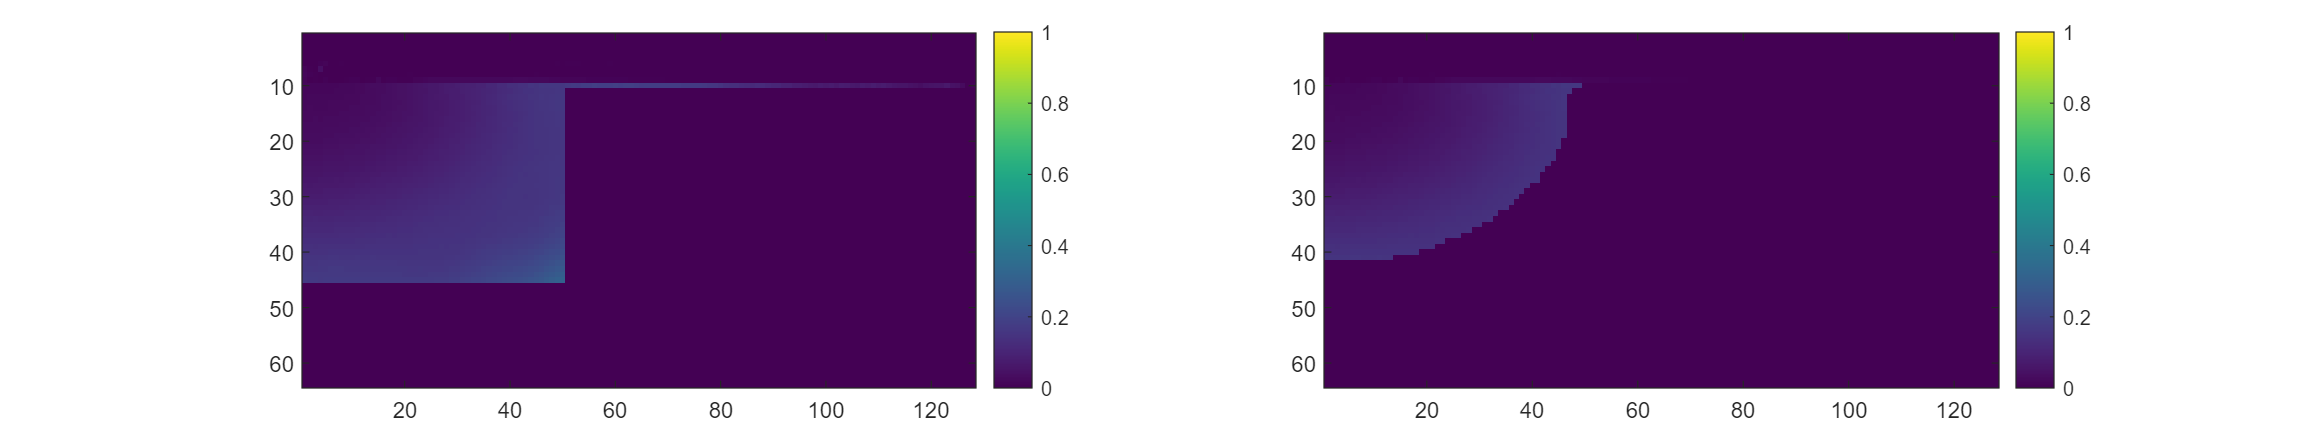

load('Musk.mat')
f = figure;
set(gcf,'position',[150 150 1600 300])
subplot(1,2,1)
image(SI_F,'CDataMapping','scaled')
colormap(mymap("viridis"))
set(gca,'CLim',[0,1])
colorbar
subplot(1,2,2)
image(SI_F.*Musk_av,'CDataMapping','scaled')
colormap(mymap("viridis"))
set(gca,'CLim',[0,1])
colorbar

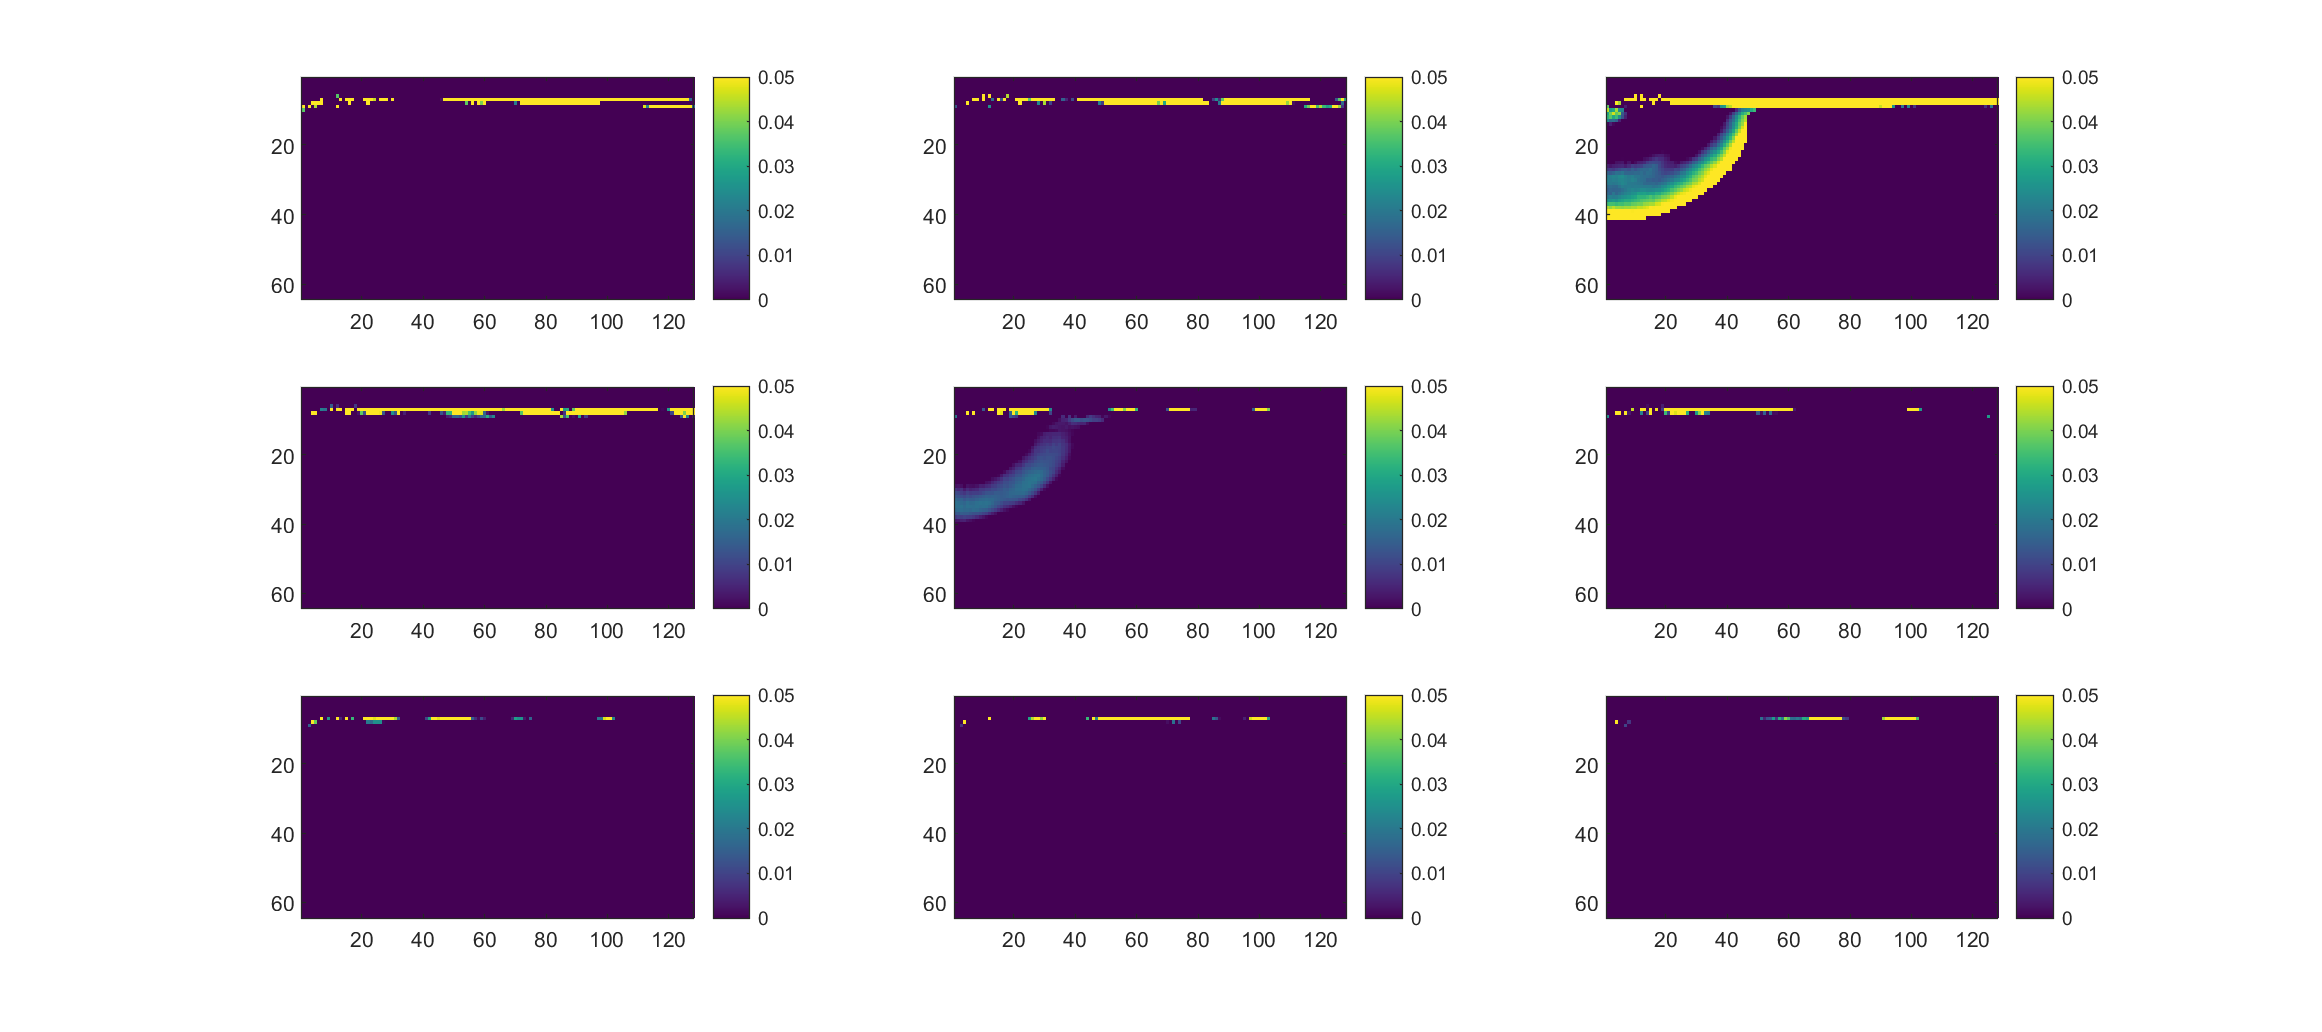

f1 = figure;
set(gcf,'position',[150 150 1800 800])
subplot(3,3,1);
for i = 1:(10-1)
    subplot(3,3,i);
    image((SI_F_D(:,:,i)-SI_F_D(:,:,10)).*Musk_av./SI_F_D(:,:,10),'CDataMapping','scaled')
    colormap(mymap("viridis"))
    set(gca,'CLim',[0,0.05])
    colorbar
end

# 函数

function [SI_A] = SI_Process(Y)
Y(Y<0.0001) = 0;
[H, W, N,~] = size(Y);
E_bc = mean(Y,4);
E_a_bc = mean(E_bc,3);
E_a2_bc = mean(E_bc.^2,3);
Var_A = E_a2_bc - E_a_bc.^2;
Y = reshape(Y,[H, W, N^2]);
Var_t = var(Y,0,3);
SI_A = Var_A ./ (Var_t);
end


function X0 = sobolr(N, P) % U [0 1]
S = 1000;
L= 100;
p = sobolset(P, 'Skip', S, 'Leap', L);
p = scramble(p, 'MatousekAffineOwen');
X0 = net(p, N);
end


function Y = soboln(X0) % N 有效区间[-3 3]
Y = icdf('Normal', X0, 0, 1);
end


function Y = sobolln(X0) % LN 有效区间[0,13]
Y = icdf('Normal', X0, 0, 1);
Y = exp(Y);
end